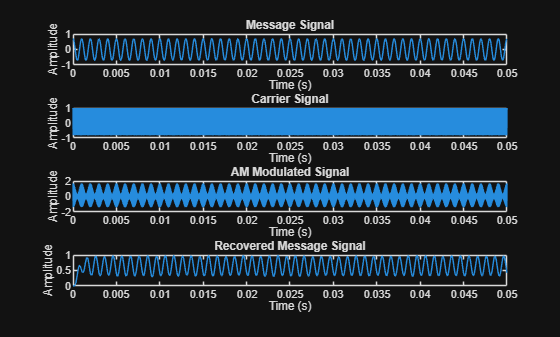

clc;
clear;
close all;

%% Parameters
fs = 100000;        % Sampling frequency
t = 0:1/fs:0.05;    % Time vector

fc = 20000;         % Carrier frequency (20 kHz)
fm = 1000;          % Message frequency (1 kHz)
Ac = 1;             % Carrier amplitude
Am = 0.7;           % Message amplitude

%% Message Signal
m = Am*cos(2*pi*fm*t);

%% Carrier Signal
c = Ac*cos(2*pi*fc*t);

%% AM Modulation
s = (1 + m).*c;

%% Add Channel Noise
snr = 20;
r = awgn(s, snr, 'measured');

%% Envelope Detection
env = abs(r);

%% Low Pass Filter to recover message
[b,a] = butter(5, fm/(fs/2));
demod = filter(b,a,env);

%% Time Domain Plots
figure;

subplot(4,1,1)
plot(t,m)
title('Message Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(4,1,2)
plot(t,c)
title('Carrier Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(4,1,3)
plot(t,s)
title('AM Modulated Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(4,1,4)
plot(t,demod)
title('Recovered Message Signal')
xlabel('Time (s)')
ylabel('Amplitude')

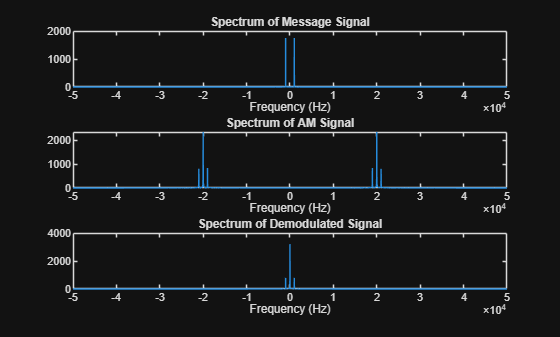


%% Frequency Spectrum
n = length(t);
f = (-n/2:n/2-1)*(fs/n);

M = abs(fftshift(fft(m)));
S = abs(fftshift(fft(s)));
D = abs(fftshift(fft(demod)));

figure

subplot(3,1,1)
plot(f,M)
title('Spectrum of Message Signal')
xlabel('Frequency (Hz)')

subplot(3,1,2)
plot(f,S)
title('Spectrum of AM Signal')
xlabel('Frequency (Hz)')

subplot(3,1,3)
plot(f,D)
title('Spectrum of Demodulated Signal')
xlabel('Frequency (Hz)')